# trainData をquaternionのままplotすることで，回帰する目標がquaternionだったら連続かどうかを確認

clc
clear
close all

curdir = pwd;
addpath(strcat(curdir, '/../../hara_functions/'));
datadir = strcat(curdir, '/../train_data_using_yoshimulibrary/');

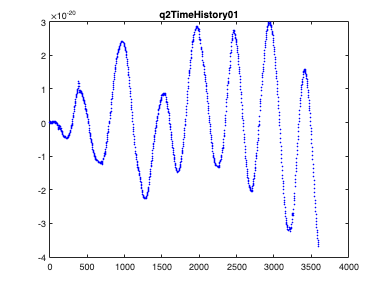

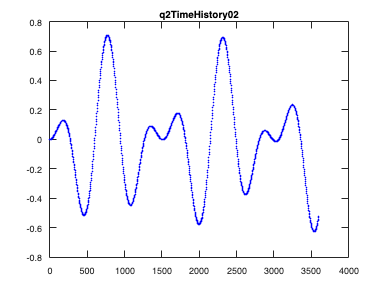

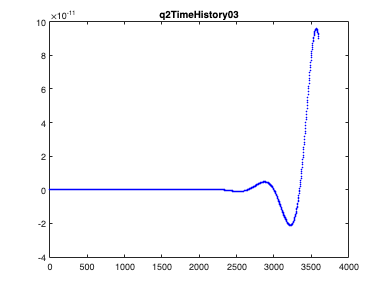

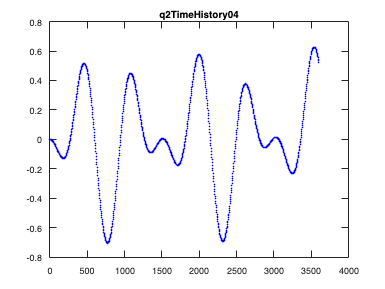

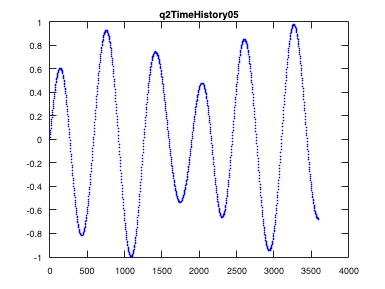

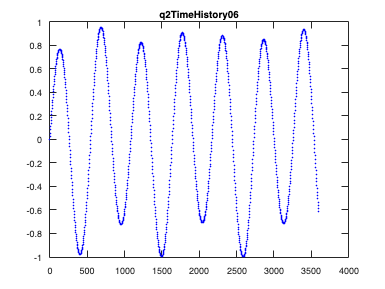

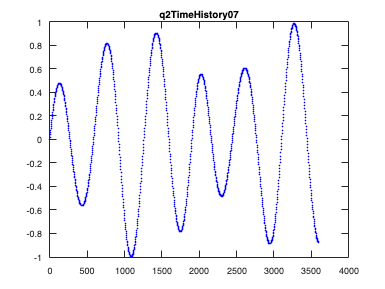

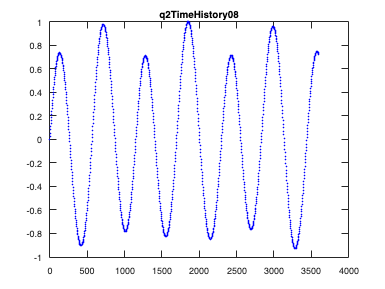

ans = 'complete the plot'

N = 29; % N個のtrain dataをplot
qElement = 2; % plotするquaternionの要素：(q1, q2, q3, q4)の定義で

plotQuaternion(N, qElement)

quaternionの要素ごとにまとめてplotする関数

function msg = plotQuaternion(N, qElement)
arguments
    N (1,1) {mustBeNumeric}
    qElement (1,1) {mustBeMember(qElement, [1, 2, 3, 4])}
end

curdir = pwd;
datadir = strcat(curdir, '/../train_data_using_yoshimulibrary/');
% train data 読み込みと plot
for i = 1:1:N
    filename = strcat(datadir, 'X_boxWing', sprintf('%03d', i), '.csv');
    df = readmatrix(filename);
    X = df;
    filename = strcat(datadir, 't_mApp_boxWing', sprintf('%03d', i), '.csv');
    df = readmatrix(filename);
    t_mApp = df;
    t = t_mApp(:,1);

    figurename = strcat('q', num2str(qElement), 'TimeHistory', sprintf('%03d', i));
    figure('Name', figurename);
    plot(t, X(:,qElement), 'b.');
    title(figurename);

end

msg = 'complete the plot';

end